# ELE 3613 Signals and Systems

## Step 1: Generate (or import) the audio signal

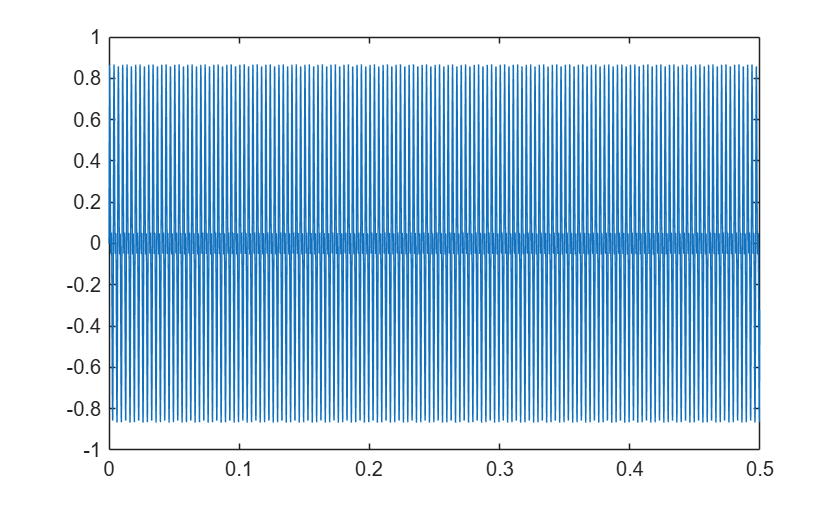

fs = 8000;                          % sampling frequency in Hz
t  = 0:1/fs:0.5-1/fs;               % 0.5 s time axis (4000 samples)
x  = 0.6*sin(2*pi*300*t) + 0.4*sin(2*pi*600*t);   % clean "audio" signal (two tones)
plot(t,x)

% To use a real recording instead, comment the four lines above and use:
% [x,fs] = audioread('speech.wav');  x = x(:,1).';  t = (0:length(x)-1)/fs;

## Step 2: Add artificial noise

rng(1)                              % same noise every run
wn   = 0.2*randn(size(x));          % broadband white noise
whis = 0.3*sin(2*pi*1500*t);        % narrowband interference ("whistle" at 1500 Hz)
xn   = x + wn + whis;               % noisy signal

## Step 3: Noise reduction, Method A: moving average (Lab 2)

y3 = movmean(xn,3);                 % 3-point moving average
y7 = movmean(xn,7);                 % 7-point moving average

## Step 4: Noise reduction, Method B: lowpass, bandpass, bandstop (Lab 5)

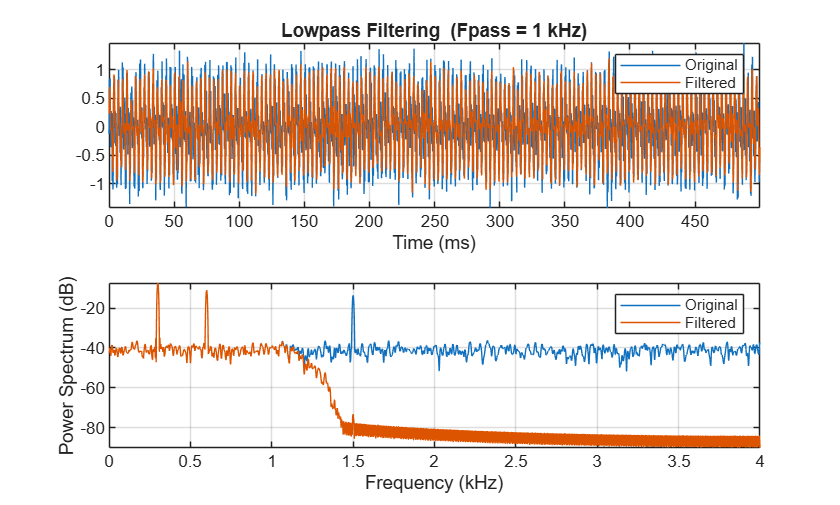

ylp = lowpass(xn, 1000, fs);            % keep f < 1000 Hz
ybp = bandpass(xn, [200 700], fs);      % keep 200 Hz to 700 Hz (both tones)
ybs = bandstop(xn, [1450 1550], fs);    % remove only the 1500 Hz whistle

% View of each filter as in Lab 5 (no output argument: MATLAB plots input, output and spectra)
figure, lowpass(xn, 1000, fs)

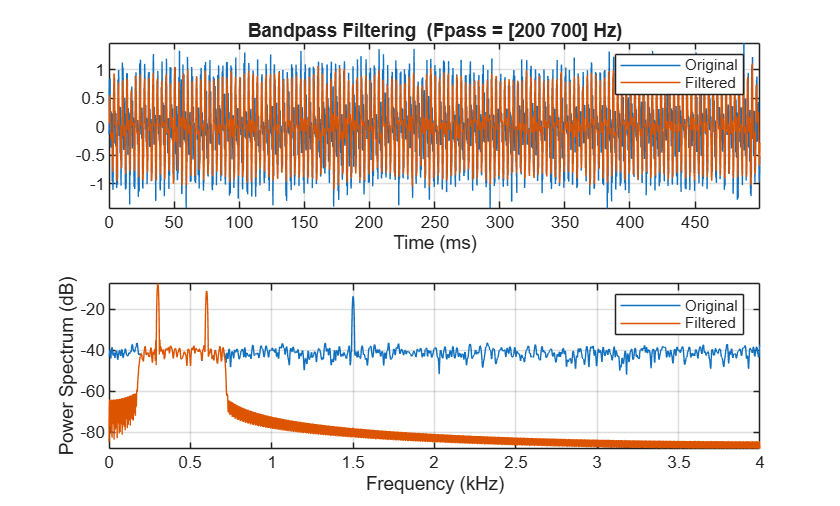

figure, bandpass(xn, [200 700], fs)

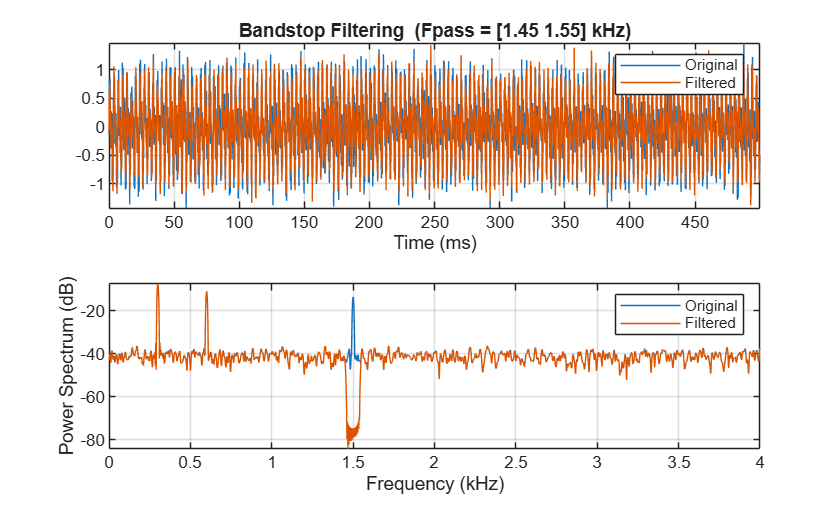

figure, bandstop(xn, [1450 1550], fs)

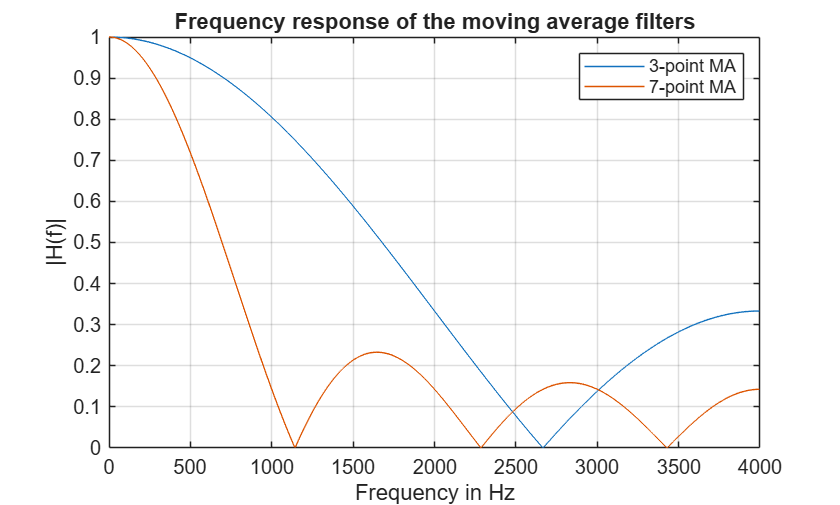


% Frequency response of the moving average for comparison (Lab 10)
figure
[H3,f3] = freqz(ones(1,3)/3, 1, 1024, fs);
[H7,f7] = freqz(ones(1,7)/7, 1, 1024, fs);
plot(f3, abs(H3), f7, abs(H7)), grid on
legend('3-point MA','7-point MA'), xlabel('Frequency in Hz'), ylabel('|H(f)|')
title('Frequency response of the moving average filters')

## Step 5: Time-domain plots

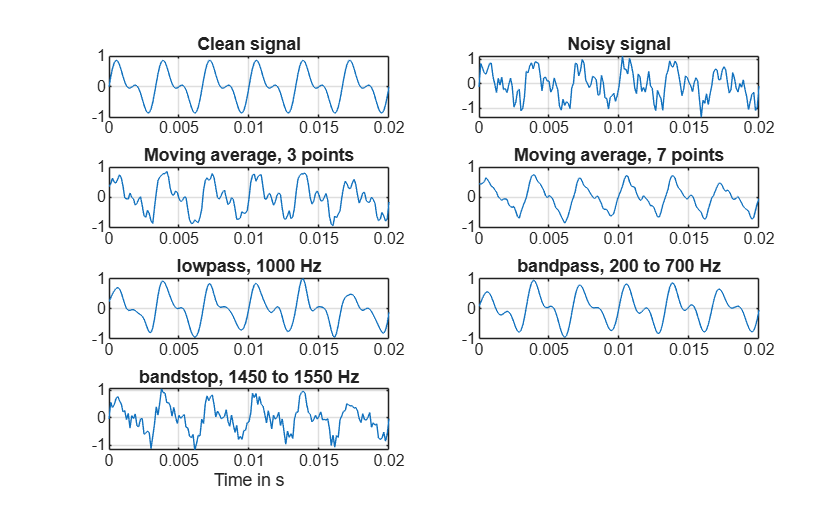

idx = t <= 0.02;                    % first 20 ms so that the waveforms are visible
figure
subplot(4,2,1), plot(t(idx), x(idx)),   grid on, title('Clean signal')
subplot(4,2,2), plot(t(idx), xn(idx)),  grid on, title('Noisy signal')
subplot(4,2,3), plot(t(idx), y3(idx)),  grid on, title('Moving average, 3 points')
subplot(4,2,4), plot(t(idx), y7(idx)),  grid on, title('Moving average, 7 points')
subplot(4,2,5), plot(t(idx), ylp(idx)), grid on, title('lowpass, 1000 Hz')
subplot(4,2,6), plot(t(idx), ybp(idx)), grid on, title('bandpass, 200 to 700 Hz')
subplot(4,2,7), plot(t(idx), ybs(idx)), grid on, title('bandstop, 1450 to 1550 Hz'), xlabel('Time in s')

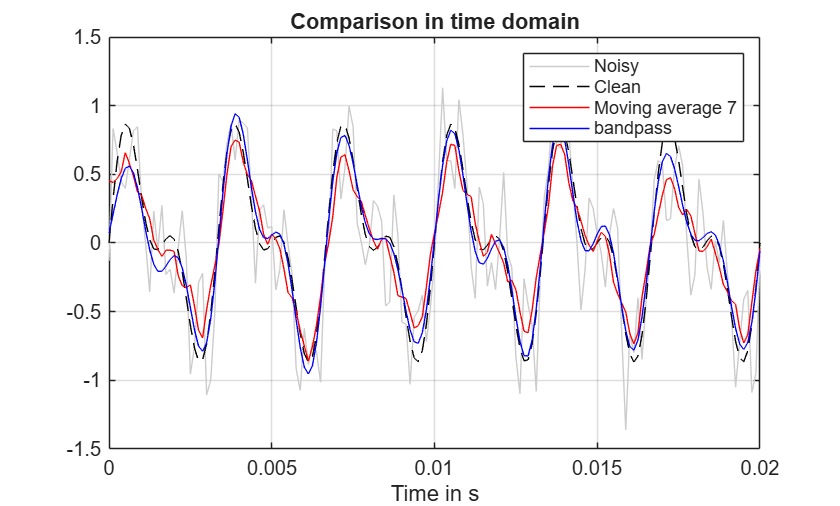


figure                              % best moving average and best filter against the clean signal
plot(t(idx), xn(idx), 'Color', [0.8 0.8 0.8]), hold on
plot(t(idx), x(idx), 'k--', t(idx), y7(idx), 'r', t(idx), ybp(idx), 'b')
grid on, legend('Noisy','Clean','Moving average 7','bandpass'), xlabel('Time in s'), title('Comparison in time domain')

## Step 6: Frequency-domain plots using the FFT

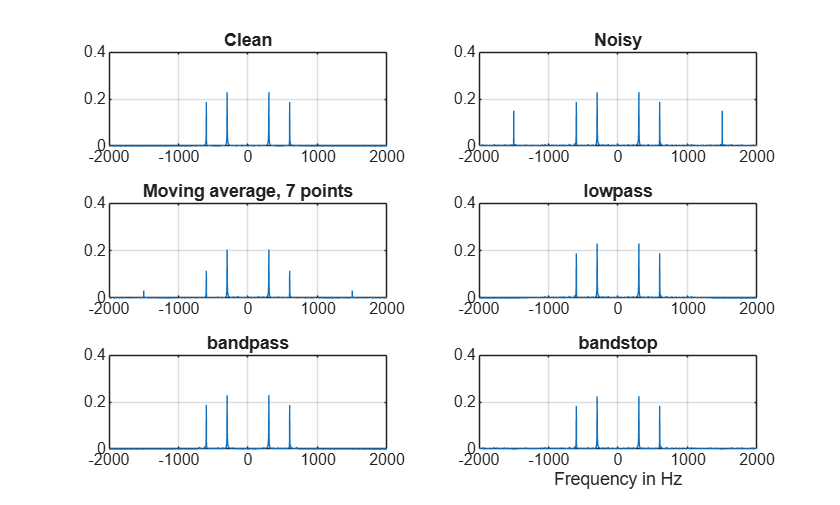

N = 2^nextpow2(length(x));          % FFT length (4096)
f = (-N/2:N/2-1)*fs/N;              % frequency axis in Hz
spec = @(s) fftshift(fft(s,N))/length(s);   % centred and scaled spectrum

sig    = {x,        xn,        y7,                  ylp,         ybp,           ybs};
titles = {'Clean','Noisy','Moving average, 7 points','lowpass','bandpass','bandstop'};
figure
for k = 1:6
    subplot(3,2,k)
    plot(f, abs(spec(sig{k}))), grid on
    xlim([-2000 2000]), ylim([0 0.4]), title(titles{k})
end
xlabel('Frequency in Hz')

## Step 7: Compare the methods (SNR and MSE against the clean signal)

snr = @(c,y) 10*log10(sum(c.^2)/sum((y-c).^2));   % signal-to-noise ratio in dB
mse = @(c,y) mean((y-c).^2);                       % mean squared error

Names = {'Noisy input';'MA 3-point';'MA 7-point';'lowpass';'bandpass';'bandstop'};
Y = {xn; y3; y7; ylp; ybp; ybs};
SNR = zeros(6,1);  MSE = zeros(6,1);
for k = 1:6
    SNR(k) = snr(x, Y{k});
    MSE(k) = mse(x, Y{k});
end
Improvement = SNR - SNR(1);
results = table(Names, SNR, MSE, Improvement)

results = 6×4 table
         Names          SNR         MSE       Improvement
    _______________    ______    _________    ___________

    {'Noisy input'}    4.8034     0.086027           0   
    {'MA 3-point' }    9.3891     0.029927      4.5857   
    {'MA 7-point' }     10.74     0.021925      5.9369   
    {'lowpass'    }    13.144     0.012606      8.3405   
    {'bandpass'   }    16.718    0.0055359      11.914   
    {'bandstop'   }    8.2606     0.038807      3.4572   

	Get insights using Copilot


## Step 8: Effect of the moving average length (optional)

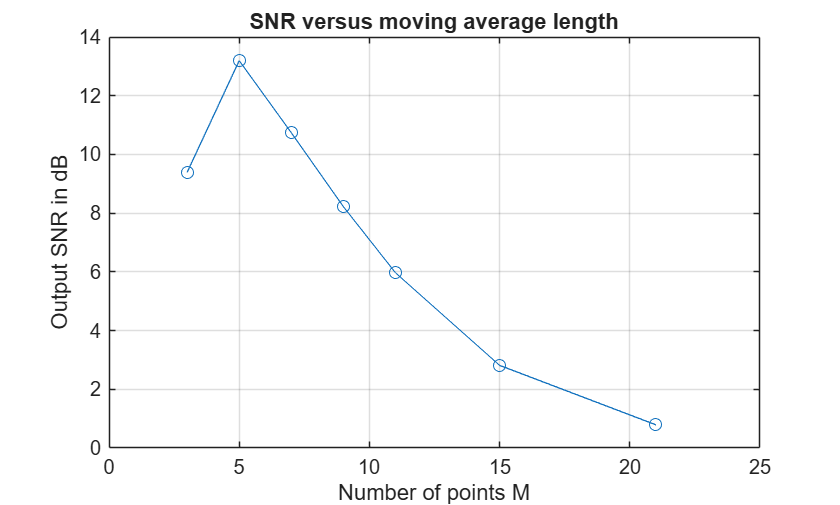

M = [3 5 7 9 11 15 21];
S = zeros(size(M));
for k = 1:length(M)
    S(k) = snr(x, movmean(xn, M(k)));
end
figure
plot(M, S, '-o'), grid on
xlabel('Number of points M'), ylabel('Output SNR in dB'), title('SNR versus moving average length')

## Step 9: Listen to the result (optional)

sound(xn, fs); pause(1) sound(ybp, fs)